# DATA

load('04-12-19_04.45 765_LA92_40degC_Turnigy_Graphene.mat');
LiPoly.RecordingTime            = meas.Time;
LiPoly.Measured_Voltage         = meas.Voltage;
LiPoly.Measured_Current         = meas.Current;
LiPoly.Measured_Temperature     = meas.Battery_Temp_degC;

nominalCap                      = 4.81; % Battery capacity in Ah taken from data.
LiPoly.Measured_SOC             = (nominalCap + meas.Ah).*100./nominalCap;  % Calculate the SOC using Coloumb Counting for comparison

## Resample the given DATA

LiPoly.RecordingTime            = LiPoly.RecordingTime(1:10:end);% converting 0.1 sec sample data to 1sec sample data
LiPoly.Measured_Voltage         = LiPoly.Measured_Voltage(1:10:end);
LiPoly.Measured_Current         = LiPoly.Measured_Current(1:10:end);
LiPoly.Measured_Temperature     = LiPoly.Measured_Temperature(1:10:end);
LiPoly.Measured_SOC             = LiPoly.Measured_SOC(1:10:end);

% Current Definition: (+) Discharging, (-) Charging
LiPoly.Measured_Current_R       = - LiPoly.Measured_Current;

% Converting seconds to hours
LiPoly.RecordingTime_Hours      = LiPoly.RecordingTime/3600;

## UKF estimation

alpha=5e-6;
[SOC_Estimated, Vt_Estimated, Vt_Error] = UKF_SOC_Estimation(LiPoly.Measured_Current_R, LiPoly.Measured_Voltage, LiPoly.Measured_Temperature,alpha);
%[SOC_Estimated, Vt_Estimated, Vt_Error] = EKF_SOC_Estimation(LiPoly.Measured_Current_R, LiPoly.Measured_Voltage, LiPoly.Measured_Temperature);


## Plot the Estimated SOc and Vt

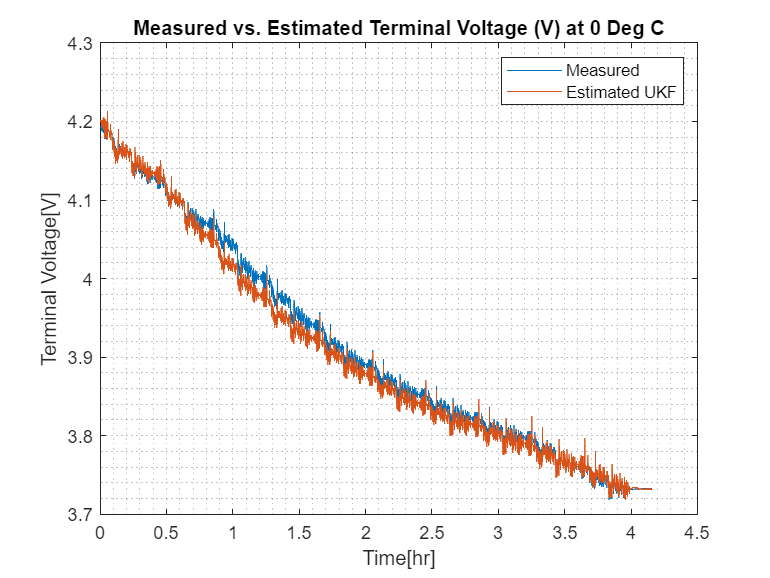

% Terminal Voltage Measured vs. Estimated
figure
plot(LiPoly.RecordingTime_Hours,LiPoly.Measured_Voltage);
hold on
plot(LiPoly.RecordingTime_Hours,Vt_Estimated);
hold off;
legend('Measured','Estimated UKF');
ylabel('Terminal Voltage[V]');xlabel('Time[hr]');
title('Measured vs. Estimated Terminal Voltage (V) at 0 Deg C')
grid minor

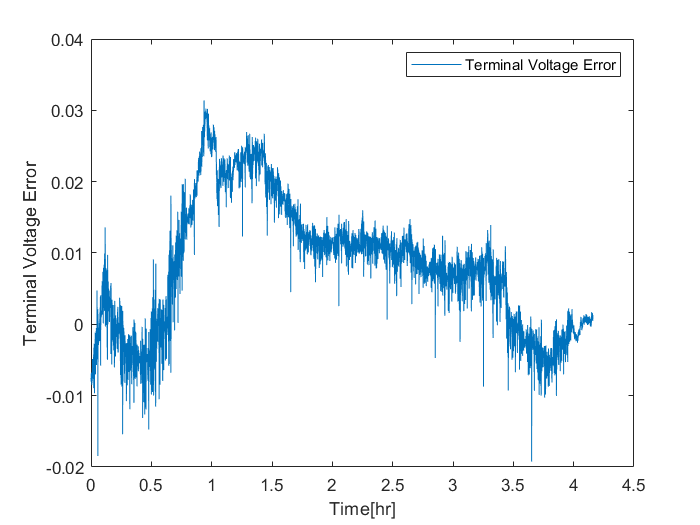

% Terminal Voltage Error
figure
plot(LiPoly.RecordingTime_Hours,Vt_Error);
legend('Terminal Voltage Error');
ylabel('Terminal Voltage Error');
xlabel('Time[hr]');

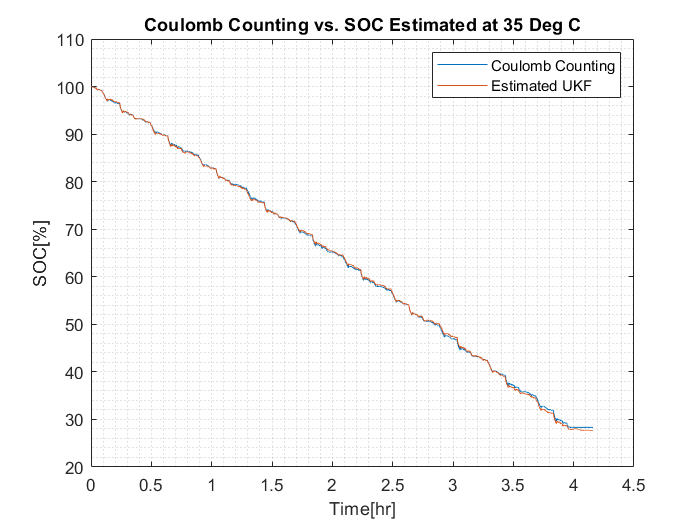

% SOC Coulomb Counting vs. Estimated
figure
plot (LiPoly.RecordingTime_Hours,LiPoly.Measured_SOC);
hold on
plot (LiPoly.RecordingTime_Hours,SOC_Estimated*100);
hold off;
legend('Coulomb Counting','Estimated UKF');
ylabel('SOC[%]');xlabel('Time[hr]');
title('Coulomb Counting vs. SOC Estimated at 35 Deg C')
grid minor

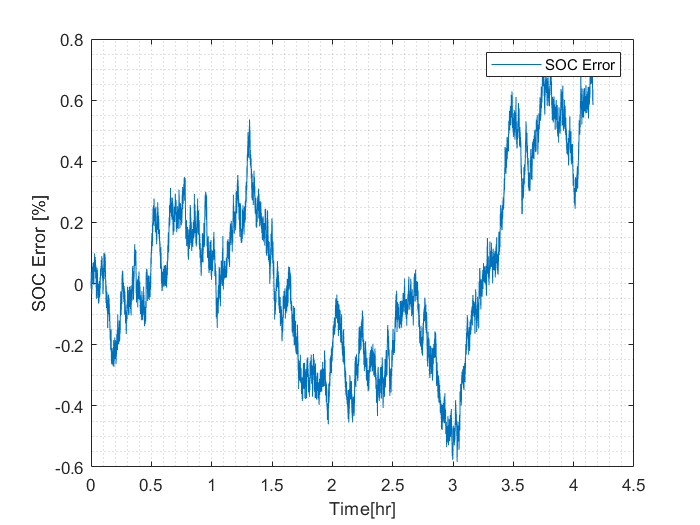

% SOC Error
figure
plot(LiPoly.RecordingTime_Hours,(LiPoly.Measured_SOC - SOC_Estimated*100));
legend('SOC Error');
ylabel('SOC Error [%]');
xlabel('Time[hr]');
grid minor

## MAX and RMS error

% Calculate RMSE and MAX of Vt and SOC
RMSE_Vt     = sqrt((sum((LiPoly.Measured_Voltage - Vt_Estimated).^2)) /(length(LiPoly.Measured_Voltage)))*1000 % mV

RMSE_Vt = 12.2263

RMSE_SOC    = sqrt((sum((LiPoly.Measured_SOC - SOC_Estimated*100).^2)) /(length(LiPoly.Measured_SOC))) % (%)

RMSE_SOC = 0.2980

Max_Vt      = max(abs(LiPoly.Measured_Voltage - Vt_Estimated))*1000 % mV

Max_Vt = 31.3976

Max_SOC     = max(abs(LiPoly.Measured_SOC - SOC_Estimated*100)) % (%)

Max_SOC = 0.7372